# Black-Litterman Portfolio Optimization

This example shows the workflow to implement the Black-Litterman model with the [Portfolio](docid:finance_ug.buk6uyz-1) class. The Black-Litterman model is an asset allocation approach that allows investment analysts to incorporate subjective views (based on investment analyst estimates) into market equilibrium returns. By blending analyst views and equilibrium returns instead of relying only on historical asset returns, the Black-Litterman model provides a systematic way to estimate the mean and covariance of asset returns. 

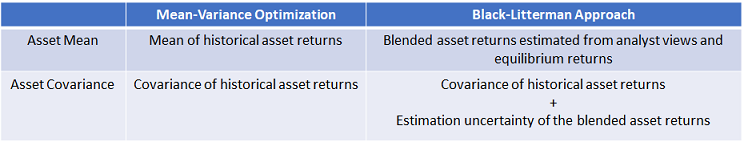

In the Black-Litterman model, the blended expected return is $\overset{-}{\mu} ={\left\lbrack P^T \Omega^{-1} P+C^{-1} \right\rbrack }^{-1} \left\lbrack P^T \Omega^{-1} q+C^{-1} \pi \right\rbrack$ and the estimation uncertainty is $\textrm{cov}\left(\mu \right)={\left\lbrack P^T \Omega^{-1} P+C^{-1} \right\rbrack }^{-1}$. To use the Black-Litterman model, you must prepare the inputs: $P,q\;,\Omega \;,\;\pi ,$ and $C$. The inputs for $P,\;q\;,\;$and $\Omega$ are view-related and defined by the investment analyst. $\pi$ is the equilibrium return and $C$ is the uncertainty in prior belief. This example guides you to define these inputs and use the resulting blended returns in a portfolio optimization. For more information on the concept and derivation of the Black-Litterman model, see the Appendix section Black-Litterman Model under a Bayesian Framework. 

## Define the Universe of Assets

The `dowPortfolio.xlsx` data set includes 30 assets and one benchmark. Seven assets from this data set comprise the investment universe in this example. The risk-free rate is assumed to be zero.

T = readtable('dowPortfolio.xlsx');

Define the asset universe and extract the asset returns from the price data.

assetNames = ["AA", "AIG", "WMT", "MSFT", "BA", "GE", "IBM"];
benchmarkName = "DJI";
head(T(:,["Dates" benchmarkName assetNames]))
retnsT = tick2ret(T(:, 2:end));
assetRetns = retnsT(:, assetNames);
benchRetn = retnsT(:, "DJI");
numAssets = size(assetRetns, 2);

## Specify Views of the Market 

The views represent the subjective views of the investment analyst regarding future market changes, expressed as  $\mathit{\mathbf{q}}\;=\mathit{\mathbf{P}}*\mu \;+\;\varepsilon ,\;\;\;\varepsilon ~N\left(0,\;\Omega \right),\;\Omega =\textrm{diag}\left(\omega_1 ,\omega_2 ,\ldotp \ldotp \ldotp \omega_v \right)$, where *v *is total number of views. For more information, see the Appendix section Assumptions and Views. With *v* views and *k* assets, $P$ is a *v*-by-*k* matrix, $\mathit{\mathbf{q}}$ is a *v*-by-1 vector, and $\Omega$ is a *v*-by-*v* diagonal matrix (representing the independent uncertainty in the views). The views do not necessarily need to be independent among themselves and the structure of $\Omega$ can be chosen to account for investment analyst uncertainties in the views [4]. The smaller the $\omega_i$ in $\Omega$, the smaller the variance in the distribution of the *i*th view, and the stronger or more certain the investor's *i*th view. This example assumes three independent views.

- AIG is going to have 5% annual return with uncertainty 1e-3. This is a weak absolute view due to its high uncertainty.

- WMT is going to have 3% annual return with uncertainty 1e-3. This is a weak absolute view due to its high uncertainty.

- MSFT is going to outperform IBM by 5% annual return with uncertainty 1e-5. This is a strong relative view due to its low uncertainty.

v = 3;  % total 3 views
P = zeros(v, numAssets);
q = zeros(v, 1);
Omega = zeros(v);

% View 1
P(1, assetNames=="AIG") = 1; 
q(1) = 0.05;
Omega(1, 1) = 1e-3;

% View 2
P(2, assetNames=="WMT") = 1; 
q(2) = 0.03;
Omega(2, 2) = 1e-3;

% View 3
P(3, assetNames=="MSFT") = 1; 
P(3, assetNames=="IBM") = -1; 
q(3) = 0.05;
Omega(3, 3) = 1e-5;

Visualize the three views in table form.

viewTable = array2table([P q diag(Omega)], 'VariableNames', [assetNames "View_Return" "View_Uncertainty"]) 

Because the returns from `dowPortfolio.xlsx` data set are daily returns and the views are on the annual returns, you must convert views to be on daily returns.

bizyear2bizday = 1/252;
q = q*bizyear2bizday; 
Omega = Omega*bizyear2bizday;

## Estimate the Covariance from the Historical Asset Returns

$\Sigma$ is the covariance of the historical asset returns.

Sigma = cov(assetRetns.Variables);

## Define the Uncertainty *C*

The Black-Litterman model makes the assumption that the structure of $C$ is proportional to the covariance $\Sigma$. Therefore, $C=\tau \Sigma$, where $\tau$ is a small constant. A smaller $\tau$ indicates a higher confidence in the prior belief of $\mu$. The work of He and Litterman uses a value of 0.025. Other authors suggest using 1/*n* where *n* is the number of data points used to generate the covariance matrix [3]. This example uses 1/*n*.

tau = 1/size(assetRetns.Variables, 1);
C = tau*Sigma;

## Market Implied Equilibrium Return 

In the absence of any views, the equilibrium returns are likely equal to the implied returns from the equilibrium portfolio holding. In practice, the applicable equilibrium portfolio holding can be any optimal portfolio that the investment analyst would use in the absence of additional views on the market, such as the portfolio benchmark, an index, or even the current portfolio [2]. In this example, you use linear regression to find a market portfolio that tracks the returns of the DJI benchmark. Then, you use the market portfolio as the equilibrium portfolio and the equilibrium returns are implied from the market portfolio. The `findMarketPortfolioAndImpliedReturn` function, defined in Local Functions, implements the equilibrium returns. This function takes historical asset returns and benchmark returns as inputs and outputs the market portfolio and the corresponding implied returns.

[wtsMarket, PI] = findMarketPortfolioAndImpliedReturn(assetRetns.Variables, benchRetn.Variables);

## Compute the Estimated Mean Return and Covariance

Use the $P,\;q\;,\;\Omega \;,\;\pi \;,$ and $C$ inputs to compute the blended asset return and variance using the Black-Litterman model.

You can compute $\overset{-}{\mu}$ and $\textrm{cov}\left(\mu \right)$ directly by using this matrix operation:

 $\overset{-}{\mu} ={\left\lbrack P^T \Omega^{-1} P+C^{-1} \right\rbrack }^{-1} \left\lbrack P^T \Omega^{-1} q+C^{-1} \pi \right\rbrack$,$\;\textrm{cov}\left(\mu \right)={\left\lbrack P^T \Omega^{-1} P+C^{-1} \right\rbrack }^{-1}$

mu_bl = (P'*(Omega\P) + inv(C)) \ ( C\PI + P'*(Omega\q));
cov_mu = inv(P'*(Omega\P) + inv(C));

Comparing the blended expected return from Black-Litterman model to the prior belief of expected return $\pi$, you find that the expected return from Black-Litterman model is indeed a mixture of both prior belief and investor views. For example, as shown in the table below, the prior belief assumes similar returns for MSFT and IBM, but in the blended expected return, MSFT has a higher return than IBM by more than 4%. This difference is due to the imposed strong view that MSFT outperforms IBM by 5%.

table(assetNames', PI*252, mu_bl*252, 'VariableNames', ["Asset_Name", ...
    "Prior_Belief_of_Expected_Return", "Black_Litterman_Blended_Expected_Return"])

## Portfolio Optimization and Results

The [Portfolio](docid:finance_ug.buk6uyz-1) object in Financial Toolbox™ implements the Markowitz mean variance portfolio optimization framework. Using a [Portfolio](docid:finance_ug.buk6uyz-1) object, you can find the efficient portfolio for a given risk or return level, and you can also maximize the Sharpe ratio. 

Use [estimateMaxSharpeRatio](docid:finance_ug.bukz4de-1) with the [Portfolio](docid:finance_ug.buk6uyz-1) object to find allocations with the maximum Sharpe ratio for the following portfolios: 

- Portfolio with asset mean and covariance from historical asset returns

- Portfolio with blended asset return and covariance from the Black-Litterman model

port = Portfolio('NumAssets', numAssets, 'lb', 0, 'budget', 1, 'Name', 'Mean Variance');
port = setAssetMoments(port, mean(assetRetns.Variables), Sigma);
wts = estimateMaxSharpeRatio(port);

portBL = Portfolio('NumAssets', numAssets, 'lb', 0, 'budget', 1, 'Name', 'Mean Variance with Black-Litterman');
portBL = setAssetMoments(portBL, mu_bl, Sigma + cov_mu);  
wtsBL = estimateMaxSharpeRatio(portBL);

ax1 = subplot(1,2,1);
idx = wts>0.001;
pie(ax1, wts(idx), assetNames(idx));
title(ax1, port.Name ,'Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
idx_BL = wtsBL>0.001;
pie(ax2, wtsBL(idx_BL), assetNames(idx_BL));
title(ax2, portBL.Name ,'Position', [-0.05, 1.6, 0]);
table(assetNames', wts, wtsBL, 'VariableNames', ["AssetName", "Mean_Variance", ...
     "Mean_Variance_with_Black_Litterman"])

When you use the values for the blended asset return and the covariance from the Black-Litterman model in a mean-variance optimization, the optimal allocations reflect the views of the investment analyst directly. The allocation from the Black-Litterman model is more diversified, as the pie chart shows. Also, the weights among the assets in the Black-Litterman model agree with the investment analyst views. For example, when you compare the Black-Litterman result with the plain mean-variance optimization result, you can see that the Black-Litterman result is more heavily invested in MSFT than in IBM. This is because the investment analyst has a strong view that MSFT will outperform IBM. 

## Local Functions

function [wtsMarket, PI] = findMarketPortfolioAndImpliedReturn(assetRetn, benchRetn)
% Find the market portfolio that tracks the benchmark and its corresponding implied expected return.

The implied return is calculated by reverse optimization. The risk-free rate is assumed to be zero. The general formulation of a portfolio optimization is given by the Markowitz optimization problem: $\underset{\omega}{\arg\max}\,\,\, \omega^T \mu- \frac{\delta}{2} \omega^T \Sigma \omega$. Here $\omega$ is an *N*-element vector of asset weights, $\mu$ is an *N*-element vector of expected asset returns, $\Sigma$ is the *N*-by-*N* covariance matrix of asset returns, and $\delta$ is a positive risk aversion parameter. Given $\delta \;$, in the absence of constraints, a closed form solution to this problem is $\omega = \frac{1}{\delta}\Sigma^{-1}\mu$. Therefore, with a market portfolio, the implied expected return is $\pi = \delta \Sigma \omega_{mkt}$. 

To compute an implied expected return, you need $ \Sigma,\ \omega_{mkt}, \ \delta$.

1) Find $\Sigma$.

$\Sigma$ is calculated from historical asset returns.

Sigma = cov(assetRetn);

2) Find the market portfolio.

To find the market portfolio, regress against the DJI. The imposed constraints are fully invested and long only: $\sum_{i=1}^n \omega_i = 1,  0 \leq \omega_i , \,\,\, \forall i \in \{1,...,n\}$

numAssets = size(assetRetn,2);
LB = zeros(1,numAssets);
Aeq = ones(1,numAssets);
Beq = 1;
opts = optimoptions('lsqlin','Algorithm','interior-point', 'Display',"off");
wtsMarket = lsqlin(assetRetn, benchRetn, [], [], Aeq, Beq, LB, [], [], opts);

3) Find $\delta$. 

Multiply both sides of $\pi = \delta \Sigma \omega_{mkt}$ with $\omega^T_{mkt}$ to output $
\delta =\frac{SharpeRatio}{\sigma_m}$.  Here, the Benchmark is assumed to be maximizing the Sharpe ratio and the corresponding value is used as market Sharpe ratio. Alternatively, you can calibrate an annualized Sharpe ratio to be 0.5, which leads to `shpr`=0.5/`sqrt`(252) [1]. $\sigma_m$ is the standard deviation of the market portfolio. 

shpr = mean(benchRetn)/std(benchRetn);
delta = shpr/sqrt(wtsMarket'*Sigma*wtsMarket); 

4) Compute the implied expected return.

Assuming that the market portfolio maximizes the Sharpe ratio, the implied return, without the effects from constraints, is computed directly as $\pi = \delta\Sigma\omega $. 

PI = delta*Sigma*wtsMarket;
end

## Appendix: Black-Litterman Model Under a Bayesian Framework

## Assumptions and Views

Assume that the investment universe is composed of *k* assets and the vector of asset returns $\mathit{\mathbf{r}}$ is modeled as a random variable, following a multivariate normal distribution $\mathit{\mathbf{r}}~N\left(\mu ,\Sigma \right)$. $\Sigma$ is the covariance from historical asset returns. The unknown model parameter is the expected return $\mu$. From the perspective of Bayesian statistics, the Black-Litterman model attempts to estimate $\mu$ by combining the investment analyst views (or "observations of the future") and some prior knowledge about $\mu$.

In addition, assume the prior knowledge that $\mu$ is a normally distributed random variable $\mu ~N\left(\pi ,\mathit{\mathbf{C}}\right)$ [1, 2]. In the absence of any views (observations), the prior mean $\pi$ is likely to be the equilibrium returns, implied from the equilibrium portfolio holding. In practice, the applicable equilibrium portfolio holding is not necessarily the equilibrium portfolio, but rather a target optimal portfolio that the investment analyst would use in the absence of additional views on the market, such as the portfolio benchmark, an index, or even the current portfolio. $C$ represents the uncertainty in the prior and the Black-Litterman model makes the assumption that the structure of$\;C$ is $\tau \Sigma$. $\tau$ is a small constant, and many authors use different values. A detailed discussion about $\tau$ can be found in [3].

Observations are necessary to perform a statistical inference on $\mu$. In the Black-Litterman model, the observations are views about future asset returns expressed at the portfolio level. A view is the expected return of a portfolio composed of the universe of *k* assets. Usually, the portfolio return has uncertainty, so an error term is added to catch the departure. Assume that there is a total of *v* views. For a view $i$, ${\mathit{\mathbf{p}}}_i$ is a row vector with dimension 1 x *k*, and $q_i$ is a scalar [2].

$q_i$ = $E\left\lbrack {\mathit{\mathbf{p}}}_i *\mathit{\mathbf{r}}\;\left|\;\mu \right.\right\rbrack +\varepsilon_{i\;} \;,\;\;i=1,2,\ldotp \ldotp \ldotp ,v$

You can stack the *v* views vertically, and $\Omega$ is the covariance of the uncertainties from all views. Assume that the uncertainties are independent. 

$\mathit{\mathbf{q}}\;=\;E\left\lbrack \mathit{\mathbf{P}}*\mathit{\mathbf{r}}\;\left|\;\mu \right.\right\rbrack +\;\varepsilon ,\;\;\varepsilon ~N\left(0,\;\Omega \right),\;\;\Omega =\textrm{diag}\left(\omega_1 ,\omega_2 ,\ldotp \ldotp \ldotp \omega_v \right)$.

Note that $\Omega$ does not necessarily need to be a diagonal matrix. The investment analyst can choose the structure of $\Omega$ to account for their uncertainties in the views [4]. 

Under the previous assumption $\mathit{\mathbf{r}}~N\left(\mu ,\Sigma \right)$, it follows that

 $\mathit{\mathbf{q}}\;=\mathit{\mathbf{P}}*\mu \;+\;\varepsilon ,\;\;\;\varepsilon ~N\left(0,\;\Omega \right),\;\Omega =\textrm{diag}\left(\omega_1 ,\omega_2 ,\ldotp \ldotp \ldotp \omega_v \right)$.

## The Bayesian Definition of the Black-Litterman Model

Based on Bayesian statistics, it is known that:$\;\textrm{posterior}\propto \textrm{likelihood}*\textrm{prior}$. 

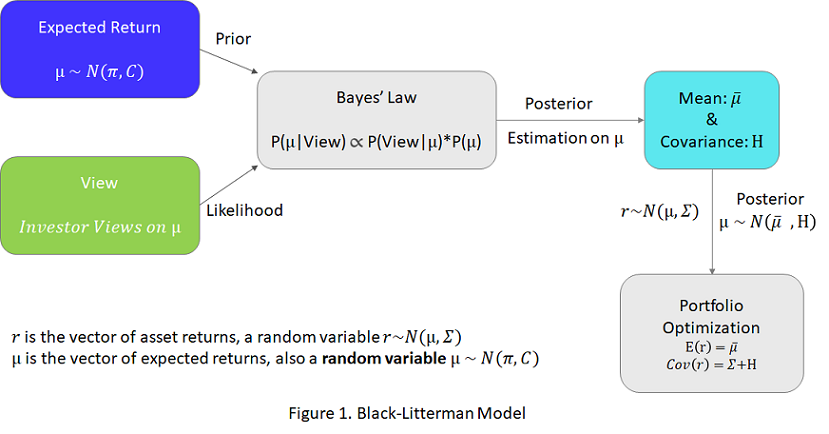

In the context of the Black-Litterman model,$\;\textrm{posterior}\propto \textrm{likelihood}*\textrm{prior}$ is expressed as $f\left(\mu \left|q\right.\right)$$\propto$ $f\left(q\left|\mu \right.\right)$*$f\left(\mu \right),$ where each Bayesian term is defined as follows [2]:

- The *likelihood* is how likely it is for the views to happen given $\mu$ and is expressed as $f\left(q\left|\mu \right.\right)\propto \exp \left\lbrack -\frac{1}{2}{\left(P\mu -q\right)}^{\prime } \Omega^{-1} \left(P\mu -q\right)\right\rbrack \ldotp$

- The *prior* assumes the prior knowledge that $\mu ~N\left(\pi ,C\right)$ and is expressed as $f\left(\mu \right)\;\;\;$$\propto \exp \left\lbrack -\frac{1}{2}{\left(\mu -\pi \right)}^{\prime } C^{-1} \left(\mu -\pi \right)\right\rbrack \ldotp$

- The* posterior* is the distribution of $\mu$ given views and is expressed as $f\left(\mu \left|q\right.\right)\;\propto \exp \left\lbrack -\frac{1}{2}{\left(P\mu -q\right)}^{\prime } \Omega^{-1} \left(P\mu -q\right)-\frac{1}{2}{\left(\mu -\pi \right)}^{\prime } C^{-1} \left(\mu -\pi \right)\right\rbrack \ldotp$ 

As previously stated, the posterior distribution of$\;\mu$ is also a normal distribution. By completing the squares, you can derive the posterior mean and covariance as $\overset{-}{\mu} ={\left\lbrack P^T \Omega^{-1} P+C^{-1} \right\rbrack }^{-1} \left\lbrack P^T \Omega^{-1} q+C^{-1} \pi \right\rbrack$, $\textrm{cov}\left(\mu \right)={\left\lbrack P^T \Omega^{-1} P+C^{-1} \right\rbrack }^{-1}$. 

Finally, by combining the Bayesian posterior distribution of$\;\mu$ and the model of asset returns $\mathit{\mathbf{r}}~N\left(\mu ,\Sigma \right)$, you then have the posterior prediction of asset returns as $\mathit{\mathbf{r}}~N\left(\overset{-}{\mu} ,\;\Sigma +\textrm{cov}\left(\mu \right)\right)$. 

## References

- Walters, J. "The Black-Litterman Model in Detail." 2014. Available at SSRN: [https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1314585](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1314585).

- Kolm, P. N., and Ritter, G. "On the Bayesian Interpretation of Black-Litterman." *European Journal of Operational Research*. Vol. 258, Number 2, 2017, pp. 564-572. 

- Attilio, M. "Beyond Black-Litterman in Practice: A Five-Step Recipe to Input Views on Non-Normal Markets." 2006. Available at SSRN: [https://papers.ssrn.com/sol3/papers.cfm?abstract_id=872577](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=872577).

- Ulf, H. "Computing implied returns in a meaningful way." *Journal of Asset Management.* Vol 6, Number 1, 2005, pp. 53-64.

*Copyright 2019 The MathWorks, Inc.*